## Fixation Grouped Analysis

- loops through all participants in the data folder assigned by script user

- grabs average movieduration of each participant

- creates a data table/cell array that holds variables of interest

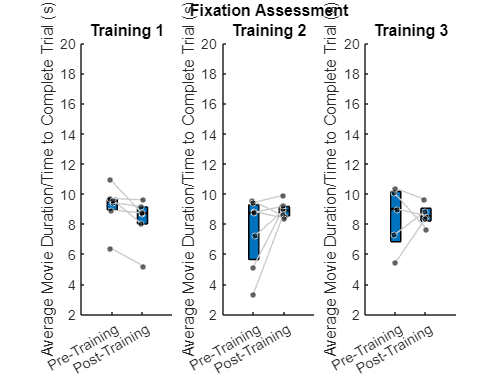

clear;
clc;


% add path where the data lives
prompt = {'Script User'};
answer = inputdlg(prompt);

%if they say nothing do nothing
if isempty(answer)
    return;
else

    user =  answer{1,1};
    [SubjectDirectory] = UserPath(user);
end
addpath(genpath(cd));
addpath(genpath(SubjectDirectory));


% load in the participant assignment table, with all the subject info
ParticipantAssignment = readtable("ParticipantAssignmentsUAB_corr.csv");
ParticipantAssignmentUCR = readtable("ParticipantAssignmentsUCR_corr.csv");
ParticipantAssignment = [ParticipantAssignment; ParticipantAssignmentUCR];


%j is a counter, it counts
 j = 1;

tt1count = 1;
tt2count = 1;
tt3count = 1;

% make a blank table, where we'll save all the important variables
DataTableFixation = [];
DataTableFixationTT1 = [];
DataTableFixationTT2 = [];
DataTableFixationTT3 = [];


for z = 5:size(ParticipantAssignment,1)
    subjectID = char(ParticipantAssignment.participant(z));
    % make sure the subject is downloaded to your computer, you won't have
    % everyone because we haven't finished everyone yet
    if exist([SubjectDirectory subjectID]) == 7 && sum(subjectID == 'fr1005') ~= 6

        % find the path where the pre-assessment data lives
        directoryPathPre = [SubjectDirectory subjectID '/pre'];

        % grab the file you want, let's start with MNRead
        FileNameFixationPre = dir([directoryPathPre '/' subjectID '_FLAPfixationflicker*.mat']);
        FileNameFixationPre = FileNameFixationPre.name;
        load(FileNameFixationPre);

        % from MNRead we want the second to last sentence time completion.
        % but let's also get levels completed in case they did a lot better

        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            DataTableFixationTT1{tt1count,1} = subjectID;
            DataTableFixationTT1{tt1count,2} = mean(movieDuration(end-15:end));
            
%tt1count = tt1count + 1;

        elseif TrainingType == '2'
            DataTableFixationTT2{tt2count,1} = subjectID;
            DataTableFixationTT2{tt2count,2} = mean(movieDuration(end-15:end));
           
         %   tt2count = tt2count + 1;

        elseif TrainingType == '3'
            DataTableFixationTT3{tt3count,1} = subjectID;
            DataTableFixationTT3{tt3count,2} = mean(movieDuration(end-15:end));
            
           % tt3count = tt3count + 1;

        else
        end

        % save these to the data table we made, also save the subject name.
        % note that this is the pre value

        DataTableFixation{j,1} = subjectID;
        DataTableFixation{j,2} = mean(movieDuration(end-15:end));
        %DataTableFixation{j,3} = NumberswLettersTime;

        % i am dumb and cannot think of a way to save these as a table without error so
        % we are doing CELLS, so make the note of which column applies to
        % which variable

        % Fixation Pre Fixation Stability Average = Column 2

        % now that you're done with the pre data, clear it out (everything
        % but the subjectID and DataTable, we need those

        clearvars -except  subjectID SubjectDirectory ParticipantAssignment DataTableFixation DataTableFixationTT1 DataTableFixationTT2 DataTableFixationTT3  tt1count tt2count tt3count  j z

        % same with post
        directoryPathPost = [SubjectDirectory subjectID '/post'];
        FileNameFixationPost = dir([directoryPathPost '/' subjectID '_FLAPfixationflicker*.mat']);
        FileNameFixationPost = FileNameFixationPost.name;

        load(FileNameFixationPost);


        % from fixation we want how long it took on average to complete the
        % last 15 trials

TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
           % DataTableFixationTT1{tt1count,1} = subjectID;
            DataTableFixationTT1{tt1count,3} = mean(movieDuration(end-15:end));
            
            tt1count = tt1count + 1;

        elseif TrainingType == '2'
           % DataTableFixation{tt2count,1} = subjectID;
            DataTableFixationTT2{tt2count,3} = mean(movieDuration(end-15:end));
           
            tt2count = tt2count + 1;

        elseif TrainingType == '3'
           % DataTableFixation{tt3count,1} = subjectID;
            DataTableFixationTT3{tt3count,3} = mean(movieDuration(end-15:end));
            
            tt3count = tt3count + 1;

        else
        end
        % save these to the data table we made, also save the subject name.
        % note that this is the post value


        DataTableFixation{j,3} = mean(movieDuration(end-15:end));
        DataTableFixation{j,4} = TrainingType;



        %Fixation Post Fixation Stability Average = Column 3

        j  = j + 1;
        clearvars -except subjectID SubjectDirectory ParticipantAssignment DataTableFixation DataTableFixationTT1 DataTableFixationTT2 DataTableFixationTT3 tt1count tt2count tt3count j z
    else
    end
end


columnNames =  {'Subject ID', 'Pre-Training Avg_MovieDuration','Post-Training Avg_MovieDuration','Training Type'};
DataTableFixation_table = cell2table(DataTableFixation,'VariableNames',columnNames);
writetable(DataTableFixation_table, [SubjectDirectory 'DataTableFixation.csv']);

condition_namesTMT = {'Pre-Training', 'Post-Training','Untrained Pre', 'Untrained Post'};

f14 = figure;
subplot(1, 3, 1)


Fix_TT1(:,1) = cell2mat({DataTableFixationTT1{:,2}});
Fix_TT1(:,2) = cell2mat({DataTableFixationTT1{:,3}});


j1 = daboxplot(Fix_TT1,'xtlabels', condition_namesTMT(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Average Movie Duration/Time to Complete Trial (s)')
title([newline 'Training 1'])
ylim([2 20])


subplot(1, 3, 2)
Fix_TT2(:,1) = cell2mat({DataTableFixationTT2{:,2}});
Fix_TT2(:,2) = cell2mat({DataTableFixationTT2{:,3}});


j2 = daboxplot(Fix_TT2,'xtlabels', condition_namesTMT(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Average Movie Duration/Time to Complete Trial (s)')
title(['Fixation Assessment' newline 'Training 2'])
ylim([2 20])


subplot(1, 3, 3)
Fix_TT3(:,1) = cell2mat({DataTableFixationTT3{:,2}});
Fix_TT3(:,2) = cell2mat({DataTableFixationTT3{:,3}});


j2 = daboxplot(Fix_TT3,'xtlabels', condition_namesTMT(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Average Movie Duration/Time to Complete Trial (s)')
title([newline 'Training 3'])
ylim([2 20])